clear; clc;
% ---- Punto 1 ----
% ---- Punto a) Pose del robot en cada paso ----
% Parámetros iniciales
x = -1;
y = -5;
theta = 0; % en radianes

% Historial de pasos (de la imagen)
v = [1, 0, 1, 0, 1, 0, 1, 0, 1, 0, 1, 0];
w = [0, pi/3, 0, pi/3, 0, pi/3, 0, pi/3, 0, pi/3, 0, pi/3];
dt = ones(1, 12);

% Inicializamos almacenamiento
poses = zeros(12, 3); % Cada fila: [x y theta]

% Cálculo de la pose paso a paso
for k = 1:12
    x = x + v(k) * cos(theta) * dt(k);
    y = y + v(k) * sin(theta) * dt(k);
    theta = theta + w(k) * dt(k);
    poses(k, :) = [x, y, theta];
end

% Mostrar tabla de resultados
T = table((1:12)', poses(:,1), poses(:,2), poses(:,3), ...
    'VariableNames', {'Paso', 'x', 'y', 'theta_rad'});
disp(T);

    Paso        x            y       theta_rad
    ____    __________    _______    _________

      1              0         -5          0  
      2              0         -5     1.0472  
      3            0.5     -4.134     1.0472  
      4            0.5     -4.134     2.0944  
      5     3.3307e-16    -3.2679     2.0944  
      6     3.3307e-16    -3.2679     3.1416  
      7             -1    -3.2679     3.1416  
      8             -1    -3.2679     4.1888  
      9           -1.5     -4.134     4.1888  
     10           -1.5     -4.134      5.236  
     11             -1         -5      5.236  
     12             -1         -5     6.2832  




% ---- Punto b) Pose final ----
pose_final = poses(end, :); % Última fila

fprintf('\nPose final del robot tras 12 pasos:\n');


Pose final del robot tras 12 pasos:


fprintf('x = %.3f m\ny = %.3f m\ntheta = %.3f rad (%.2f°)\n', ...
    pose_final(1), pose_final(2), pose_final(3), rad2deg(pose_final(3)));

x = -1.000 m
y = -5.000 m
theta = 6.283 rad (360.00°)


% ---- Punto 2 ----
clear; clc;

% Parámetros del robot
radio_rueda = 0.1;   % Radio de rueda (m)
L_eje = 0.4;         % Distancia entre ruedas (m)
dt2 = 1.0;           % Paso de tiempo (s)

% Datos extraídos de la tabla
omegaR = [4.582, 4.773, 5.291, 5.960, 6.490, ...
         -1.168, -1.364, 5.960, 5.291, 4.773, ...
          4.582, 4.773, 5.291, 5.960, 6.490, ...
          6.686, 6.490, 5.960, 5.291, 4.773, 4.582];

omegaL = [1.701, 2.353, 3.676, 4.856, 5.618, ...
         13.735, 13.472, 4.856, 3.676, 2.353, ...
          1.701, 2.353, 3.676, 4.856, 5.618, ...
          5.881, 5.618, 4.856, 3.676, 2.353, 1.701];

N2 = length(omegaR);  % 21 pasos

% Inicialización
vr = zeros(1, N2);           % Velocidad lineal
wr = zeros(1, N2);           % Velocidad angular
xr = zeros(1, N2 + 1);       % Posición x
yr = zeros(1, N2 + 1);       % Posición y
thetar = zeros(1, N2 + 1);   % Orientación

% Pose inicial
xr(1) = 0; yr(1) = 0; thetar(1) = 0;

% Cálculo paso a paso
for k = 1:N2
    vr(k) = (radio_rueda / 2) * (omegaR(k) + omegaL(k));
    wr(k) = (radio_rueda / L_eje) * (omegaR(k) - omegaL(k));

    % Integración de la pose
    thetar(k+1) = thetar(k) + wr(k) * dt2;
    xr(k+1) = xr(k) + vr(k) * cos(thetar(k+1)) * dt2;
    yr(k+1) = yr(k) + vr(k) * sin(thetar(k+1)) * dt2;
end

vr_ext      = [vr, NaN];
wr_ext      = [wr, NaN];
omegaR_ext  = [omegaR, NaN];
omegaL_ext  = [omegaL, NaN];
xr_ext      = xr'; % ya tiene 22 elementos
yr_ext      = yr';
theta_ext   = rad2deg(thetar');

T2 = table((0:N2)', ...
    vr_ext', ...
    wr_ext', ...
    omegaR_ext', ...
    omegaL_ext', ...
    xr_ext, yr_ext, theta_ext, ...
    'VariableNames', {'t_s', 'v_mps', 'w_rps', 'omega_R', 'omega_L', 'x_m', 'y_m', 'theta_deg'});

% Mostrar la tabla
disp(T2);

    t_s     v_mps      w_rps     omega_R    omega_L       x_m         y_m        theta_deg 
    ___    _______    _______    _______    _______    _________    ________    ___________

     0     0.31415    0.72025     4.582      1.701             0           0              0
     1      0.3563      0.605     4.773      2.353       0.23613      0.2072         41.267
     2     0.44835    0.40375     5.291      3.676       0.32274     0.55282         75.931
     3      0.5408      0.276      5.96      4.856        0.2521     0.99557         99.064
     4      0.6054      0.218      6.49      5.618      0.024596      1.4862         114.88
     5     0.62835    -3.7257    -1.168     13.735      -0.34284      1.9673       

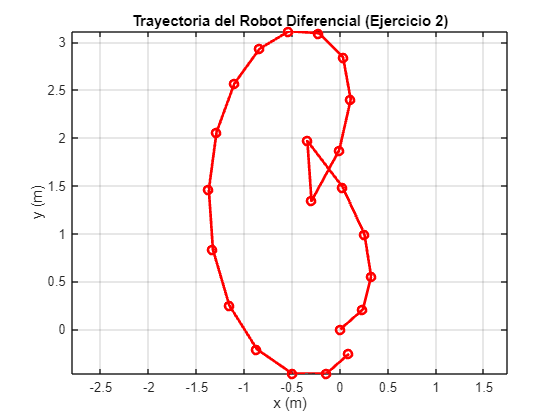


% Graficar trayectoria
figure;
plot(xr, yr, 'r-o', 'LineWidth', 2);
xlabel('x (m)');
ylabel('y (m)');
title('Trayectoria del Robot Diferencial (Ejercicio 2)');
grid on;
axis equal;

% ---- Punto 3 ----
% Punto 3 - Trayectoria circular
clear; clc;

% Parámetros del robot
r = 0.1;     % Radio de rueda (m)
L = 0.4;     % Distancia entre ruedas (m)
dt = 1.0;    % Paso de tiempo (s)
R = 20;      % Radio de la trayectoria deseada (m)
v = 1.0;     % Velocidad lineal del robot (m/s)

% Cálculo de w y velocidades angulares
w = v / R;
omegaR = (2*v + w*L) / (2*r);
omegaL = (2*v - w*L) / (2*r);

% Número de pasos de simulación
N = 126;

% Inicialización
xr = zeros(1, N+1);
yr = zeros(1, N+1);
thetar = zeros(1, N+1);  % en radianes
vr = zeros(1, N);
wr = zeros(1, N);
omegaR_arr = omegaR * ones(1, N);
omegaL_arr = omegaL * ones(1, N);

% Simulación
for k = 1:N
    vr(k) = (r / 2) * (omegaR + omegaL);
    wr(k) = (r / L) * (omegaR - omegaL);

    thetar(k+1) = thetar(k) + wr(k)*dt;
    xr(k+1) = xr(k) + vr(k)*cos(thetar(k+1))*dt;
    yr(k+1) = yr(k) + vr(k)*sin(thetar(k+1))*dt;
end

% Tabla de datos
T3 = table((0:N-1)', vr', wr', ...
           omegaR_arr', omegaL_arr', ...
           xr(1:end-1)', yr(1:end-1)', rad2deg(thetar(1:end-1))', ...
           'VariableNames', {'t_s', 'v_mps', 'w_rps', ...
                             'omega_R', 'omega_L', ...
                             'x_m', 'y_m', 'theta_deg'});

disp(T3);

    t_s    v_mps    w_rps    omega_R    omega_L      x_m          y_m        theta_deg
    ___    _____    _____    _______    _______    ________    __________    _________

      0      1      0.05      10.1        9.9             0             0          0  
      1      1      0.05      10.1        9.9       0.99875      0.049979     2.8648  
      2      1      0.05      10.1        9.9        1.9938       0.14981     5.7296  
      3      1      0.05      10.1        9.9        2.9825       0.29925     8.5944  
      4      1      0.05      10.1        9.9        3.9626       0.49792     11.459  
      5      1      0.05      10.1        9.9        4.9315       0.74532     14.324  
      6      1      0.05      1

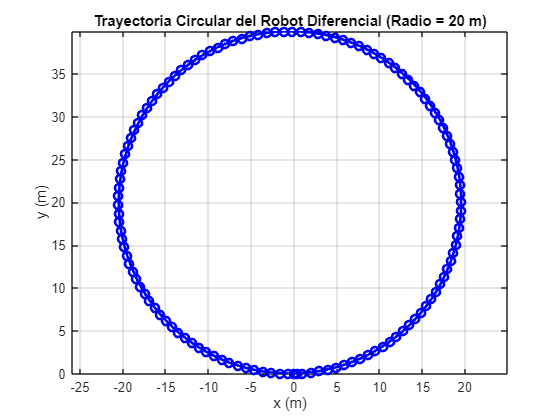


% Gráfica de trayectoria
figure;
plot(xr, yr, 'b-o', 'LineWidth', 2);
xlabel('x (m)');
ylabel('y (m)');
title('Trayectoria Circular del Robot Diferencial (Radio = 20 m)');
grid on;
axis equal;